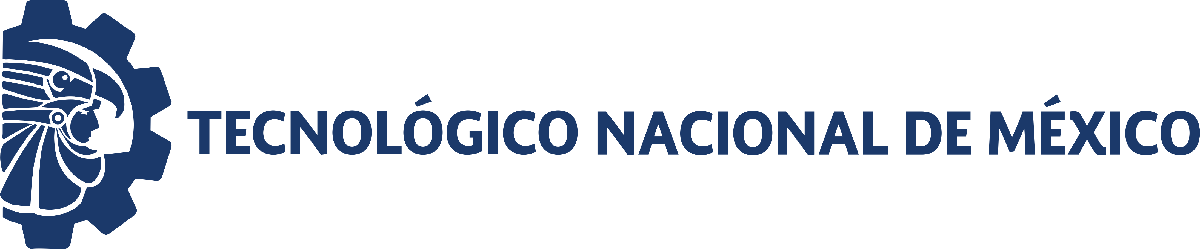                                 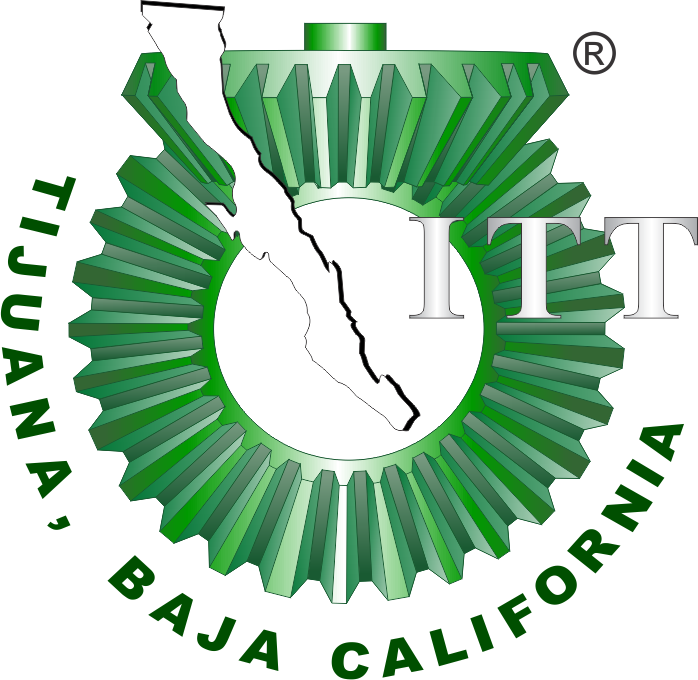

# Práctica 4: Modelado y control del sistema endócrino

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

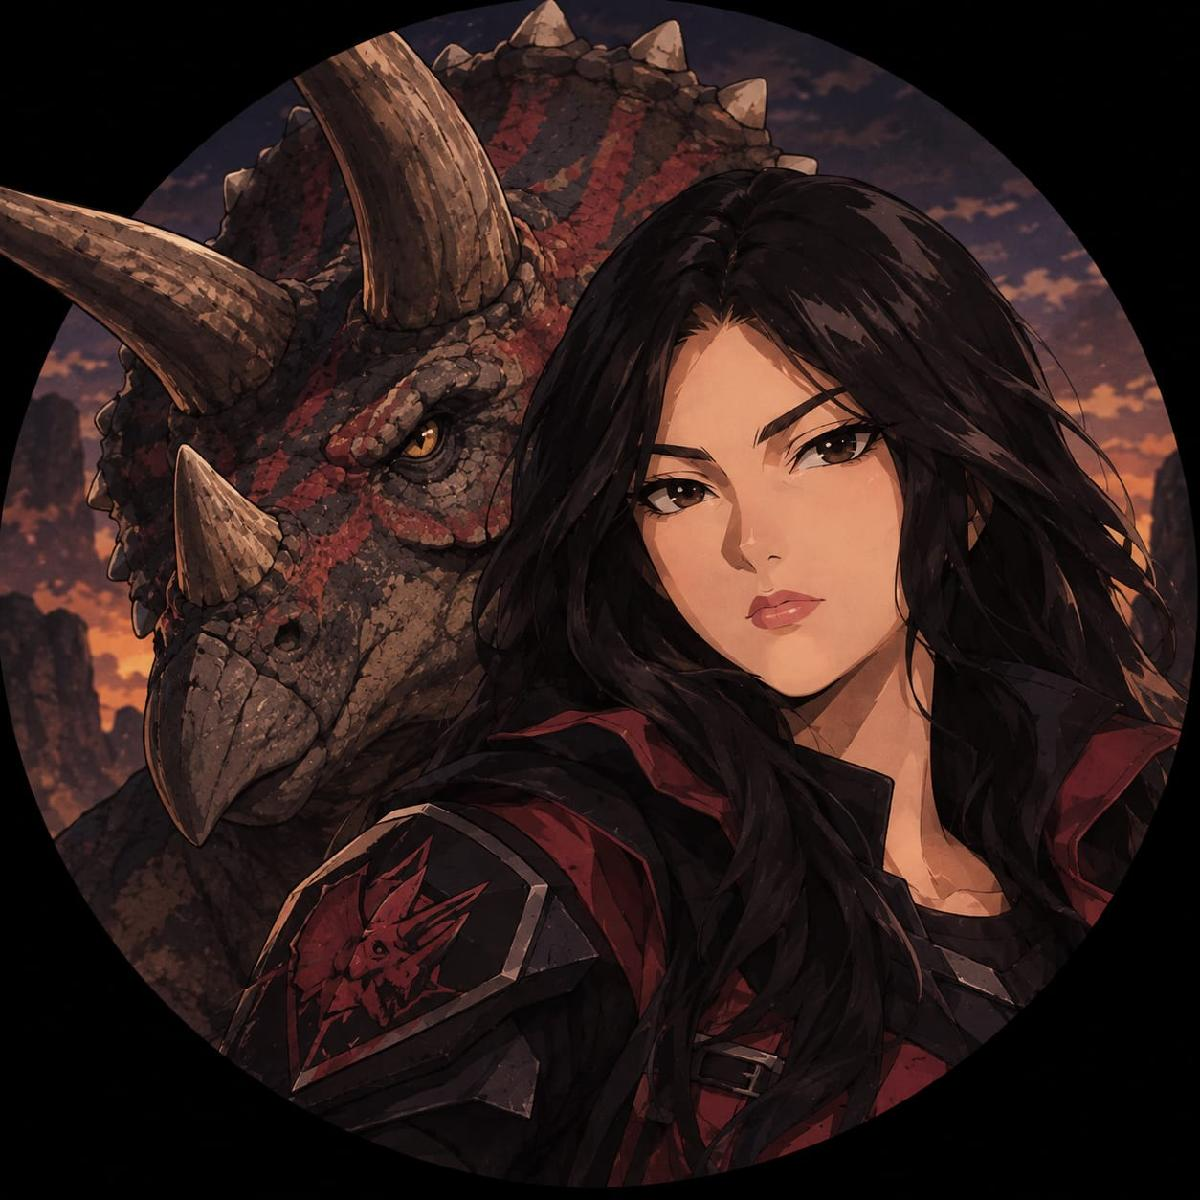

Nombre del alumno: Kenia Yasdit Contreras Jiménez

Número de control: 23212188

Correo institucional: l23212188**@tijuana.tecnm.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('Sistemaa4')                
parameters.StopTime = '15';           
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';
x = sim('Sistemaa4',parameters);         

## `Respuestas: Ve(t), Control, Caso, PID y EID`

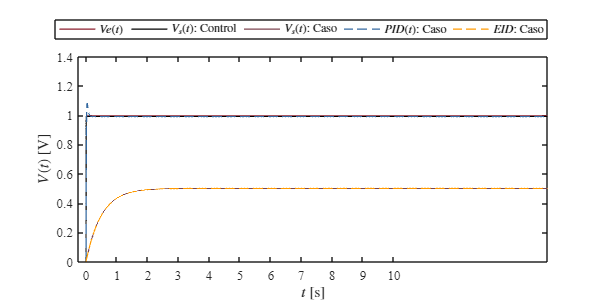

plotsignals(x.t,x.Ve,x.Control,x.Caso,x.PID,x.EID,'Respuesta_endocrino')

## Respuestas de simulación

function plotsignals (t,x1,x2,x3,x4,x5,signal)
    set(figure(),'color','w')
    set(gcf,'units','inches','position',[1,1,7,3.5])
    set(gca,'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;
    clr1 = [139, 30, 45] / 255;
    clr2 = [0.5, 0.5, 0.5] / 255;
    clr3 = [124, 68, 79] / 255;
    clr4 = [51, 104, 160] / 255;
    clr5 = [255, 154, 0] / 255;

    order = [clr1; clr2; clr3; clr4; clr5]; colororder(order)
    xlabel('$t$ [s]','Interpreter','latex')
    ylabel('$V(t)$ [V]','Interpreter','latex')
    xlim([-0.25 10]); xticks(0:1:10)

    
    plot(t,x1,'-',t,x2,'-',t,x3,'-',t,x4,'--',t,x5,'--','LineWidth',1)
    L = legend('$Ve(t)$','$V_{s}(t)$: Control','$V_{s}(t)$: Caso','$PID(t)$: Caso','$EID$: Caso');

    set(L,'interpreter','latex','location','northoutside','orientation','horizontal')
    ylim([0 1.4]); yticks(-0.2:0.2:1.4)

    exportgraphics(gcf,[signal,'_matlab.pdf'],'ContentType','vector')
end

